ЛАБОРАТОРНА РОБОТА №6

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

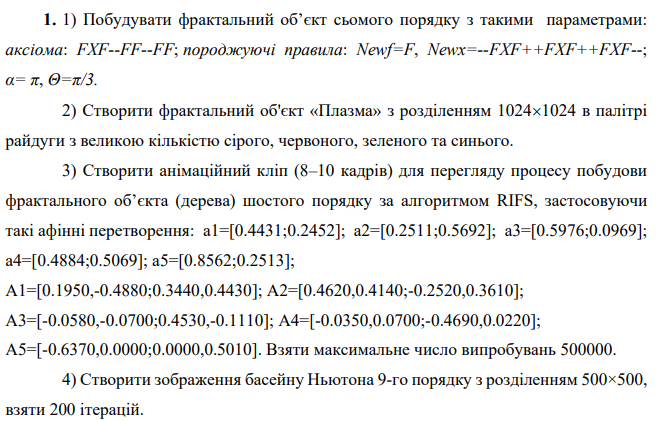

До завдання 1

function [X,Y]=Dracon1()
Lmax=7;
% Функція, що повертає зображення дракона, Lmax — порядок дракона
% породжуючі правила
Axiom='FXF--FF--FF'; Newf='F'; Newx='--FXF++FXF++FXF--'; Newy='';
teta=pi/3; alpha=pi; p=[0;0];
% звертання до функції, що повертає координати кутових точок дракона
p=CoordDragon(p,Lmax,Axiom,Newf,Newx,Newy,alpha,teta);
M=size(p,2);
X=p(1:1,1:M);% створення вектора, що містить Х-ві координати кутових точок дракона
Y=p(2:2,1:M);% створення вектора, що містить Y-ві координати кутових точок дракона
figure; plot(X,Y,'Color','b'); set(gca,'xtick',[],'ytick',[]); set(gca,'XColor','w','YColor','w');
end


function z=DraconString(Lmax,Axiom,Newf,Newx,Newy,n,tmp)
% Функція, що повертає L-систему
if n<=Lmax
 if n==1 tmp=Axiom; 
 end
 M=length(tmp); tmp1=' ';
 for i=1:M
 if tmp(i)=='F' tmp1=strcat(tmp1,Newf); 
 end
 if tmp(i)=='X' tmp1=strcat(tmp1,Newx); 
 end
 if tmp(i)=='Y' tmp1=strcat(tmp1,Newy); 
 end
 if not(tmp(i)=='F') &&not(tmp(i)=='X') &&not(tmp(i)=='Y')
 tmp1=strcat(tmp1,tmp(i)); 
 end
 end
 tmp=tmp1; n=n+1; tmp=DraconString(Lmax,Axiom,Newf,Newx,Newy,n,tmp);
end
z=tmp;
end

function z=DrawFractal(NTrial,x,y,A1,A2,A3,A4, A5,a1,a2,a3,a4, a5,Cod)
X1=zeros(NTrial,1); Y1=zeros(NTrial,1); X=x; Y=y;
for m=1:NTrial
Np=1+round((size(Cod,1)-1)*rand(1,1)); Rule=Cod(Np,:);
for i=1:length(Rule)
tmp=Rule(length(Rule)+1-i);
if tmp=='0' [X Y]=affnew(X,Y,A1,a1); end
if tmp=='1' [X Y]=affnew(X,Y,A2,a2); end
if tmp=='2' [X Y]=affnew(X,Y,A3,a3); end
if tmp=='3' [X Y]=affnew(X,Y,A4,a4); end
if tmp=='4' [X Y]=affnew(X,Y,A5,a5); end
end
X1(m)=X; Y1(m)=Y;
end
plot(X1,Y1,'.','MarkerSize',1,'MarkerEdgeColor','k');
end


До завдання 2

% plasma2222
n = 10;
imgSize = 2^n+1;
% Initialization
z = zeros(imgSize,imgSize);
z(1,1)  = 64*rand;
z(1,imgSize) = 64*rand;
z(imgSize,1) = 64*rand;
z(imgSize,imgSize) = 64*rand;
infLim = imgSize;
for i = n:-1:1
    delta = 2^i;
    infLim = (infLim+1)/2;
    % Compute diamond points
    for j = infLim:delta:imgSize
        for k = infLim:delta:imgSize
            z(j,k) = (z(j-delta/2,k-delta/2)+z(j-delta/2,k+delta/2)+...
                z(j+delta/2,k-delta/2)+z(j+delta/2,k+delta/2))/4+...
                delta*randn;
        end
    end
    
    % Compute square points
    for j = infLim:delta:imgSize
        for k = infLim:delta:imgSize
            if (k-delta>0)
                z(j,k-delta/2) = mean([z(j-delta/2,k-delta/2) ...
                    z(j+delta/2,k-delta/2) ...
                    z(j,k-delta) z(j,k)]) + delta*randn;
            else
                z(j,k-delta/2) = mean([z(j-delta/2,k-delta/2) ...
                    z(j+delta/2,k-delta/2) ...
                    z(j,k)]) + delta*randn;
            end
            if (k+delta<=imgSize)
                z(j,k+delta/2) = mean([z(j-delta/2,k+delta/2) ...
                    z(j+delta/2,k+delta/2) ...
                    z(j,k) z(j,k+delta)]) + delta*randn;
            else
                z(j,k+delta/2) = mean([z(j-delta/2,k+delta/2) ...
                    z(j+delta/2,k+delta/2) ...
                    z(j,k)]) + delta*randn;
            end            
            if (j-delta>0)
                z(j-delta/2,k) = mean([z(j-delta,k) z(j,k) ...
                    z(j-delta/2,k-delta/2) ...
                    z(j-delta/2,k+delta/2)]) + delta*randn;
            else
                z(j-delta/2,k) = mean([z(j,k) ...
                    z(j-delta/2,k-delta/2) ...
                    z(j-delta/2,k+delta/2)]) + delta*randn;
            end            
            if (j+delta<=imgSize)
                z(j+delta/2,k) = mean([z(j,k) z(j+delta,k) ...
                    z(j+delta/2,k-delta/2) ...
                    z(j+delta/2,k+delta/2)]) + delta*randn;
            else
                z(j+delta/2,k) = mean([z(j,k) ...
                    z(j+delta/2,k-delta/2) ...
                    z(j+delta/2,k+delta/2)]) + delta*randn;
            end
        end
    end
end
mapa = hsv;

mymap = [1 1 1  %
        1 0 0   %
        0 1 0   %
        0 0 1   %
        1 1 1]; %

figure(1), imagesc(z), colormap(mapa)
%%
% Cycle colors for 60 seconds
for i = 1:600
    pause(0.1)
    mapa(1:64,:) = [mapa(2:64,:); mapa(1,:)];
    colormap(mapa)
end


До завдання 3


function z=Cristal3()

Niter = 6; NTrial = 50000;

x1=0; y1=0; x2=1; y2=0; x3=1/2; y3=sin(pi/3); j=1; Flag=0;
while Flag==0
    tmpx=rand(1,1); tmpy=sqrt(3)/2*rand(1,1);
    if(-sqrt(3)*tmpx+tmpy<=0)&&(sqrt(3)*tmpx+tmpy-sqrt(3)<=0)
        x=tmpx; y=tmpy; Flag=1;
    end
end
k=1;
for m=1:Niter
    for i=1:4^m 
        Tmp(k)=system2(i-1,4); 
        k=k+1; 
    end
end
Q(1)=4;
for m=2:Niter 
    Q(m)=Q(m-1)+4^m; 
end
n=1; s='0'; M=1;
while n<=length(Tmp)
    m=1;
    while n>Q(m) 
        m=m+1; 
    end
    if m==1
        S(n,1:1)=s;
    else
        S(n,1:1)=s;
        for i=2:m 
            S(n,1:i)=strcat(S(n,:),s); 
        end
    end
    n=n+1;
end
for i=1:k-1
    tmp=num2str(Tmp(i)); m=1;
    while i>Q(m) 
        m=m+1; 
    end
    tmp1(1:m)=S(i,1:m);
    for m=1:length(tmp)
        tmp1(length(tmp1)-m+1:length(tmp1)-m+1)=tmp(length(tmp)-m+1:length(tmp)-m+1);
    end
    Cod(i,1:length(tmp1))=tmp1;
end
A1=[0.1950, -0.4880; 0.3440, 0.4430]; 
A2=[0.4620, 0.4140; -0.2520, 0.3610];
A3=[-0.0580, -0.0700; 0.4530, -0.1110]; 
A4=[-0.0350, 0.0700; -0.4690, 0.0220];
A5=[-0.6370, 0.0000; 0.0000, 0.5010];

a1=[0.4431; 0.2452]; 
a2=[0.2511; 0.5692]; 
a3=[0.5976; 0.0969]; 
a4=[0.4884; 0.5069]; 
a5 = [0.8562; 0.2513];

figure; hold on;
set(gca,'xtick',[],'ytick',[]); 
set(gca,'XColor','w','YColor','w');
DrawFractal(NTrial,x,y,A1,A2,A3,A4,A5,a1,a2,a3,a4,a5,Cod); 
hold off

end



function [X,Y]=affnew(x,y,A,a)
R=[x;y]; R=A*R+a; X=R(1); Y=R(2);
end



function z=system2(D,m)
n=1;
while D>=m^n n=n+1; end
    if n>1
        a=floor(D/m^(n-1))*10^(n-1); b=mod(D,m^(n-1));
        if b>=m
            b=system2(b,m);
        end
        z=a+b;
    else z=D;
    end
end


function RIFSclip()

Niter = 6; NTrial = 50000;

figure;
i=5;
while i<=NTrial
    Cristal3(i);
    pause(0.3);
    i=i*5;
end
title('derevo');
end


До завдання 4

function Newton_fractal4()

n=9;
maxIteration = 200;
minRe = -1;
maxRe = 1;
minIm = -1;
maxIm = 1;
xResolution = 500;
yResolution = 500;

eps = 10e-5;
Roots=exp((0:(n-1))*(2*pi)*1i/n);
Image = zeros(yResolution,xResolution,3);
dRe=(maxRe-minRe)/(xResolution-1);
dIm=(maxRe-minRe)/(yResolution-1);

for i=1:yResolution
    for j=1:xResolution
        z=minRe+(j-1)*dRe+(minIm+(i-1)*dIm)*1i;
        for iteration=1:maxIteration
            delta=z*(z^(-n)-1)/n;
            z=z+delta;
            if(abs(delta)<eps)
                break;
            end
        end
        [err,k]=min(abs(Roots-z));
        if(err<=eps)
            Image(i,j,:)=[(k-1)/n,1,1-iteration/maxIteration];
        else 
            Image(i,j,:)=0;
        end
    end
end
image(hsv2rgb(Image));
set(gca,'xtick',[],'ytick',[]);
set(gca,'xColor','w','yColor','w');
title('Басейн Ньютона')

end